Playing hood_m.wav at 24000 Hz with duration 0.18 seconds and 4429 samples


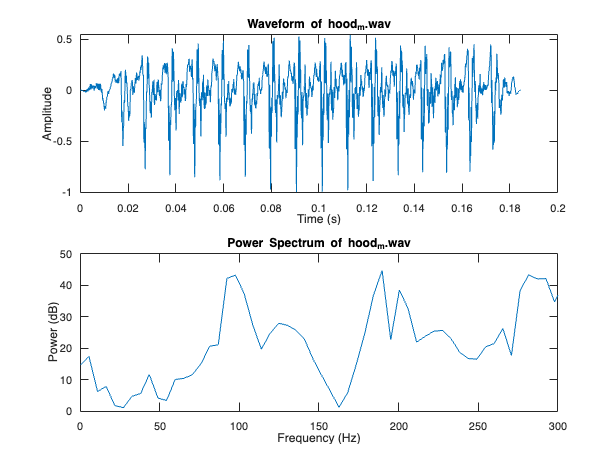

file_1 = 'hood_m.wav';
[audio, fs, duration, numSamples] = playAudio(file_1);

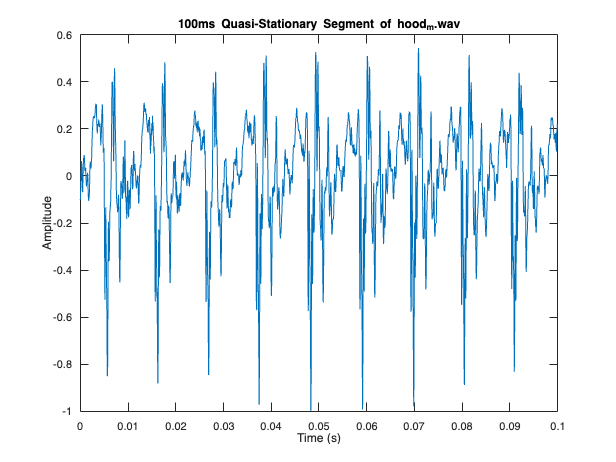

Window Size: 480 samples (20.00 ms)
Overlap: 240 samples (10.00 ms)
FFT Length (N): 2048

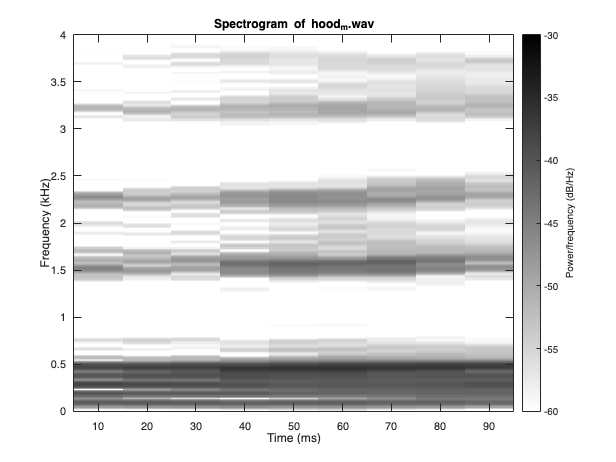

% select a 100ms quasi-stationary segment
segmentDuration = 0.1;
segment = extractCenterSegment(audio, fs, segmentDuration, file_1);
plotSpectrogram(segment, fs, file_1);

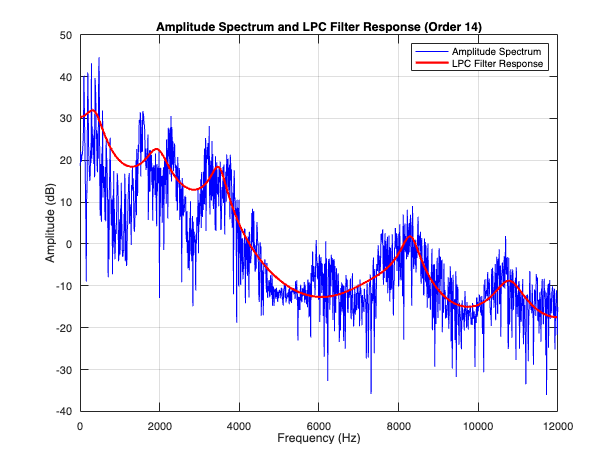

lpcOrder = 14;
plotLPCResponse(segment, fs, lpcOrder);

[formants] = estimateFormants(segment, fs, lpcOrder);

Estimated Formant Frequencies (Hz):
F1: 353.80 Hz
F2: 1940.57 Hz
F3: 3485.82 Hz


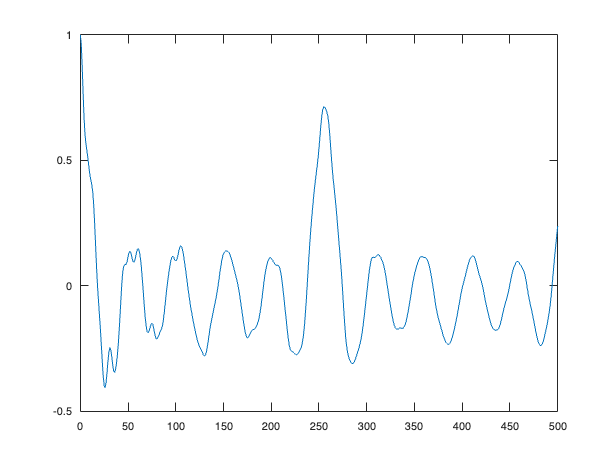

Estimated F0 using autocorrelation: 94.12 Hz


f0_estimate = estimateF0ByAutoCorrelation(segment, fs);

f0_power = estimateF0ByPowerSpectrum(segment, fs);

Estimated F0 using power spectrum: 90.00 Hz


f0 = mean(pitch(segment, fs));
fprintf('Estimated F0 using pitch function: %.2f Hz\n', f0);

Estimated F0 using pitch function: 93.10 Hz


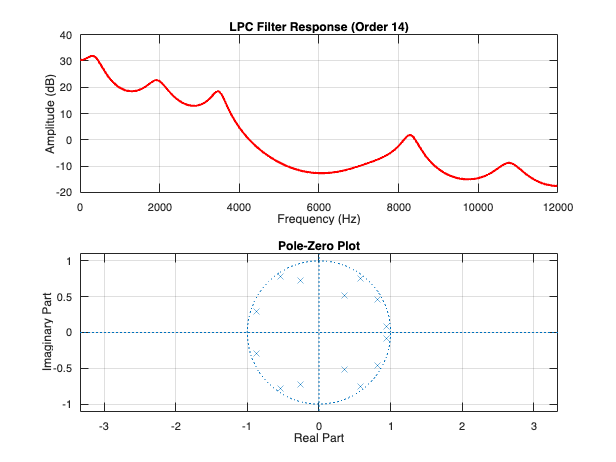

plotLPCPoleZero(segment, fs, lpcOrder);

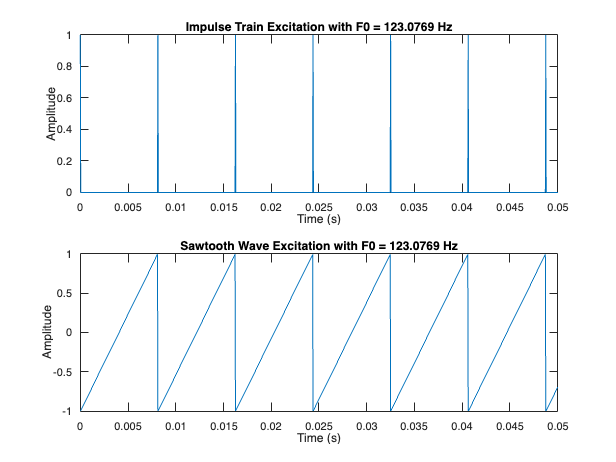

[synthesizedImpulse, synthesizedSawtooth] = synthesizeLPC(segment, fs, f0_estimate, lpcOrder, 1);

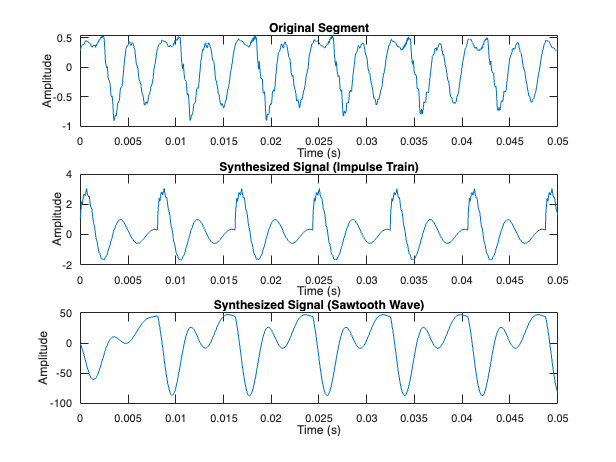

plotSynthesis(segment, fs, synthesizedImpulse, synthesizedSawtooth);